## Hearing Aid for Mild Hearing Loss

This program captures sound through the microphone and amplifies it in real time. It is useful for people with mild hearing loss who cannot hear low-pitched sound clearly.

### Tools Used:

- Audio Toolbox

- DSP System Toolbox

### Program:

# Screen Configuration

screen = get(0,'ScreenSize');
P1 = [50 300 screen(3)/2 screen(4)/2];
P2 = [620 80 screen(3)/2 screen(4)/2];

# Microphone Parameters

samplesPerSecond = 1024;
framesPerSecond = 44100;
t = 30;
numPlays = (t*framesPerSecond) / samplesPerSecond;

# Audio Recording

mic = audioDeviceReader;
mic.SamplesPerFrame = samplesPerSecond;
mic.SampleRate = framesPerSecond;

# Audio Playback

audioPlayer = audioDeviceWriter('SampleRate',framesPerSecond);

# Scope Parameters

scope = dsp.TimeScope('SampleRate',framesPerSecond,'TimeSpan',0.1,...
   'Position',P1,'YLimits',[-1 1]);
scope.ShowGrid = 1;
scope.ShowLegend = 1;

# Spectrum Analyzer

graph = dsp.SpectrumAnalyzer('SampleRate',framesPerSecond,'Position',P2,...
    'PlotAsTwoSidedSpectrum',false);
graph.SpectrumType = 'Spectrogram';

# Stream Loop

while numPlays>0               
    data = step(mic);
    step(audioPlayer, double(data));
    step(scope,data);
    step(graph,data);
    numPlays = numPlays-1; 
end

# Release Hardware

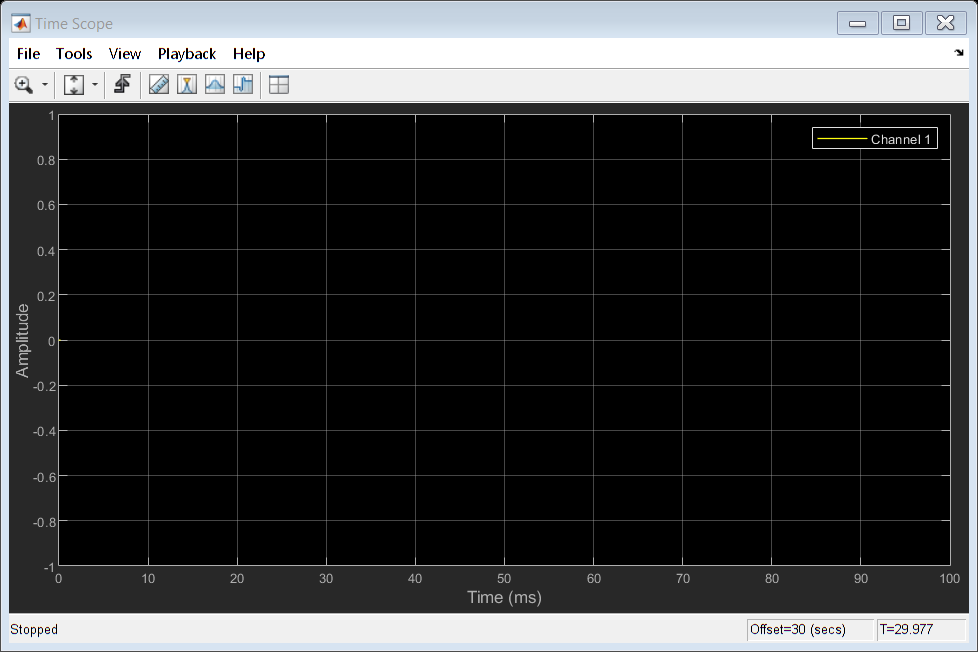

release(mic);
release(audioPlayer);
release(scope);

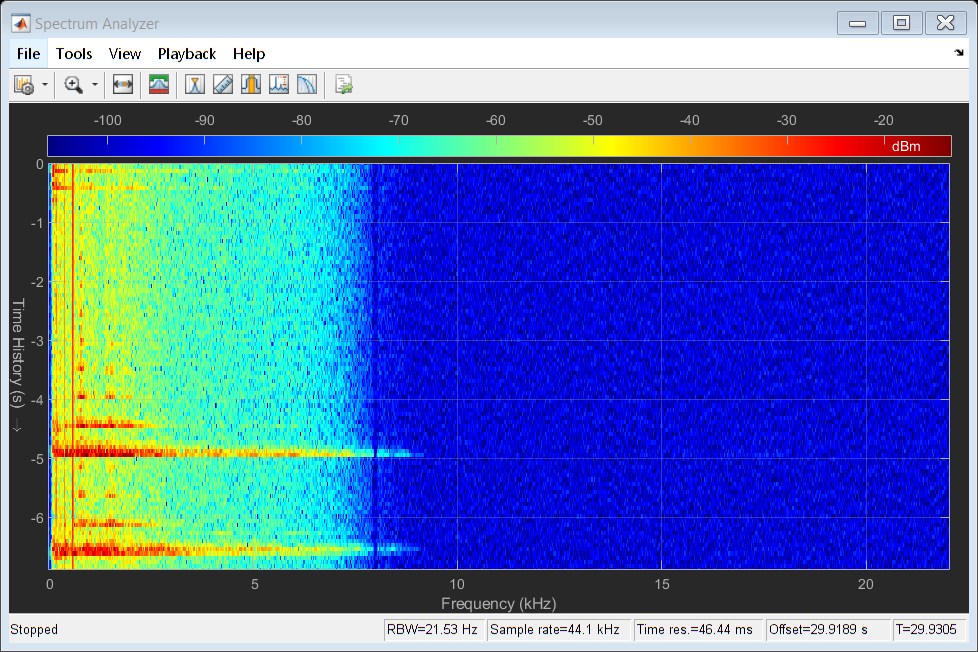

release(graph);